A = [0, 1; 900, 0]

A =      0     1
   900     0


B = [0; -9]

B =      0
    -9


C = [600, 0]

C =    600     0


D = 0

D = 0

Studio raggiungibilità

CO = ctrb(A, B)

CO =      0    -9
    -9     0


rank(CO)

ans = 2

Studio osservabilità

OB = obsv(A, C)

OB =    600     0
     0   600


rank(OB)

ans = 2

Costruzione osservatore con autovalori -120 e -180

new_eig = [-120, -180];
L = place(A', C', new_eig)';
A_ob = A-L*C

A_ob = 	1.0e+04 *

   -0.0300    0.0001
   -2.1600         0


eig(A_ob)

ans =  -180.0000
 -120.0000


Costruzione sistema retroazionato con autovalori -40 e -60

new_eig = [-40, -60];
K = place(A, B, new_eig);
A_ = A-B*K

A_ = 	1.0e+03 *

         0    0.0010
   -2.4000   -0.1000


eig(A_)

ans =   -40.0000
  -60.0000


Posto alfa = -1

C_ = C-D*K

C_ =    600     0


alfa = -1;
B_ = alfa*B

B_ =      0
     9


D_ = alfa*D

D_ = 0

Sistema dell'osservatore

sys_ob = ss(A_ob, B_, C_, D_)


sys_ob =
 
  A = 
              x1         x2
   x1       -300          1
   x2  -2.16e+04          0
 
  B = 
       u1
   x1   0
   x2   9
 
  C = 
        x1   x2
   y1  600    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Retroazione degli stati

sys = ss(A_, B_, C_, D_)


sys =
 
  A = 
          x1     x2
   x1      0      1
   x2  -2400   -100
 
  B = 
       u1
   x1   0
   x2   9
 
  C = 
        x1   x2
   y1  600    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Sistema del regolatore

A_reg = [A, -B*K; L*C, A-B*K-L*C]

A_reg = 	1.0e+04 *

         0    0.0001         0         0
    0.0900         0   -0.3300   -0.0100
    0.0300         0   -0.0300    0.0001
    2.2500         0   -2.4900   -0.0100


B_reg = [alfa*B; alfa*B]

B_reg =      0
     9
     0
     9


C_reg = [C, -D*K; zeros(1,2), C-D*K]

C_reg =    600     0     0     0
     0     0   600     0


D_reg = [alfa*D; alfa*D]

D_reg =      0
     0


sys_reg = ss(A_reg, B_reg, C_reg, D_reg)


sys_reg =
 
  A = 
              x1         x2         x3         x4
   x1          0          1          0          0
   x2        900          0      -3300       -100
   x3        300          0       -300          1
   x4   2.25e+04          0  -2.49e+04       -100
 
  B = 
       u1
   x1   0
   x2   9
   x3   0
   x4   9
 
  C = 
        x1   x2   x3   x4
   y1  600    0    0    0
   y2    0    0  600    0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



Risposta sistema retroazionato ad ingresso a onda quadra 0.5Hz, ampiezza 2

t = 0:0.01:10;
r = 2*sign(sin(2*pi*0.5*t));

x_0 1

x_0 = [0; 0; 0; 0]

x_0 =      0
     0
     0
     0


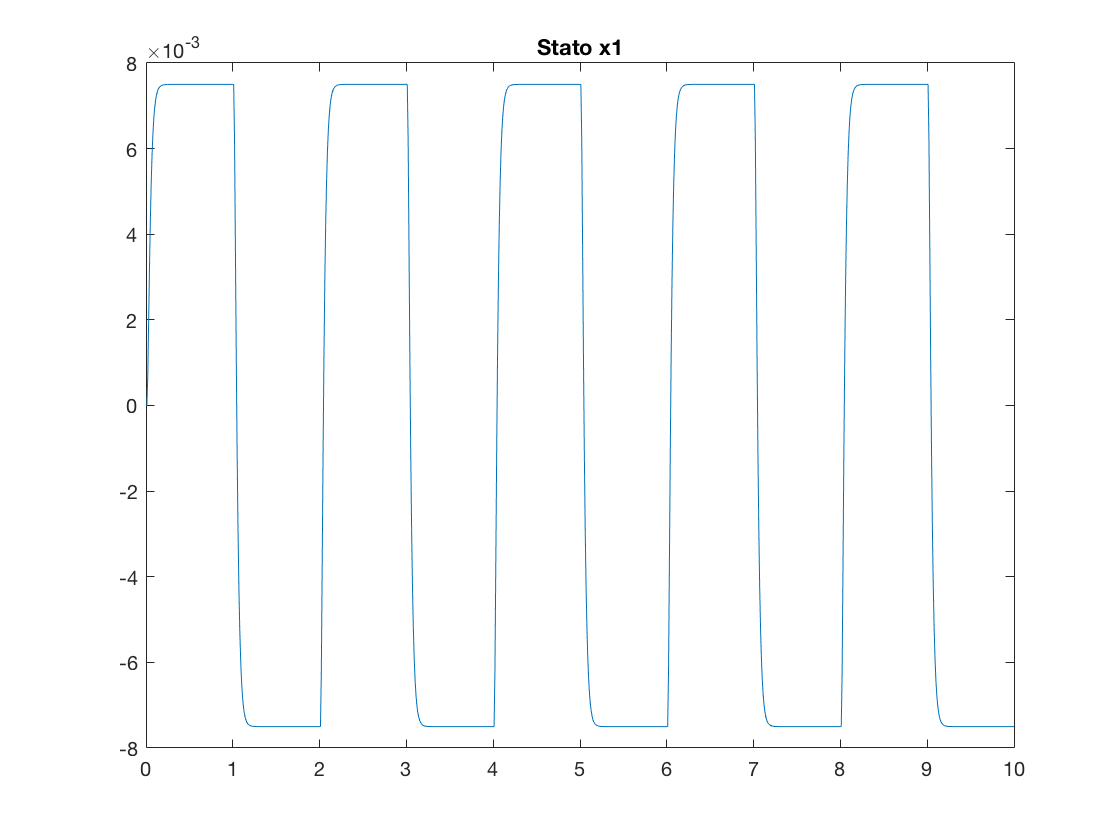


[Y, T, X] = lsim(sys_reg, r, t, x_0);
figure(1)
plot(T, X(:,1))
title('Stato x1')

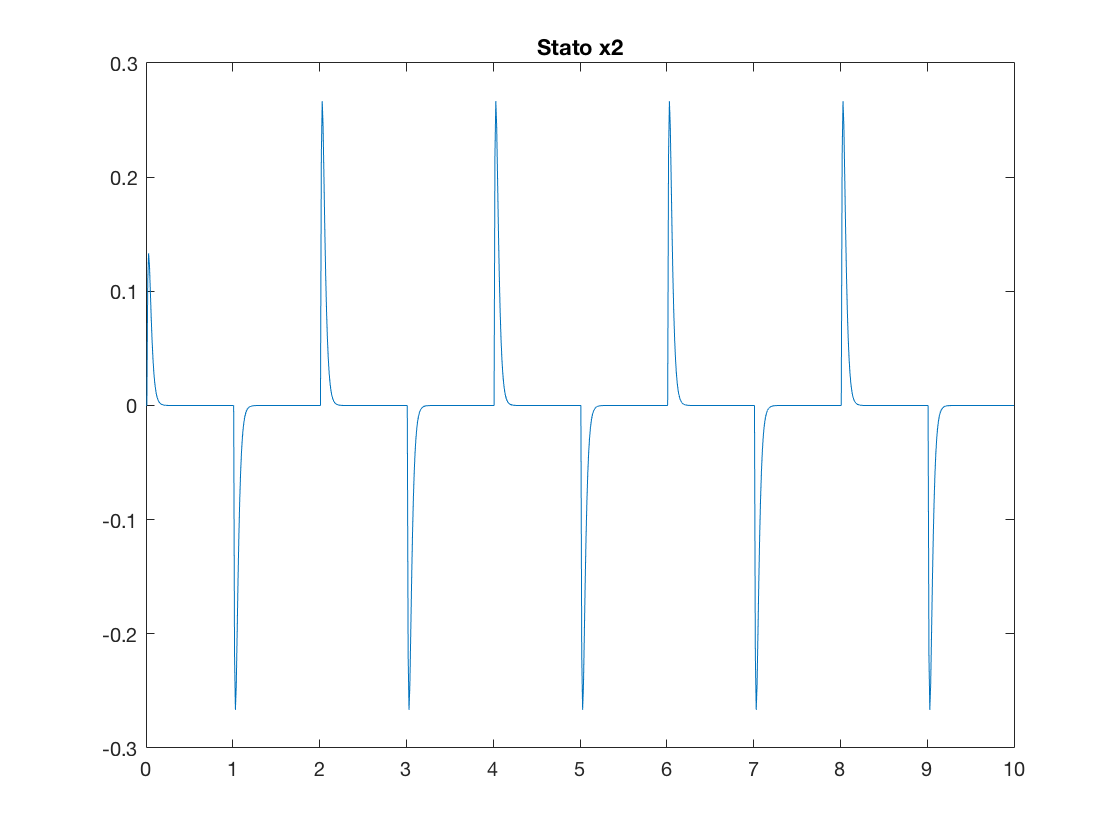


figure(2)
plot(T, X(:,2))
title('Stato x2')

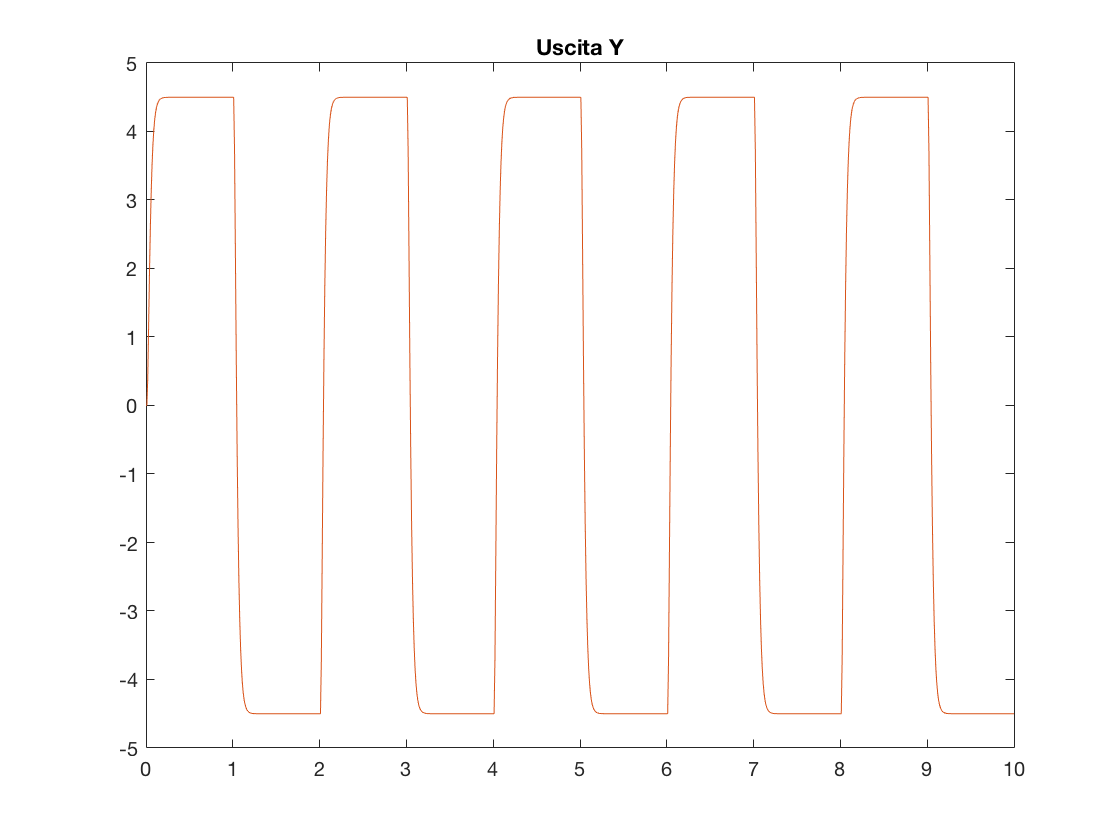


figure(3)
plot(T, Y)
title('Uscita Y')

x_0 2

x_0 = [0.01; 0; 0; 0]

x_0 =     0.0100
         0
         0
         0


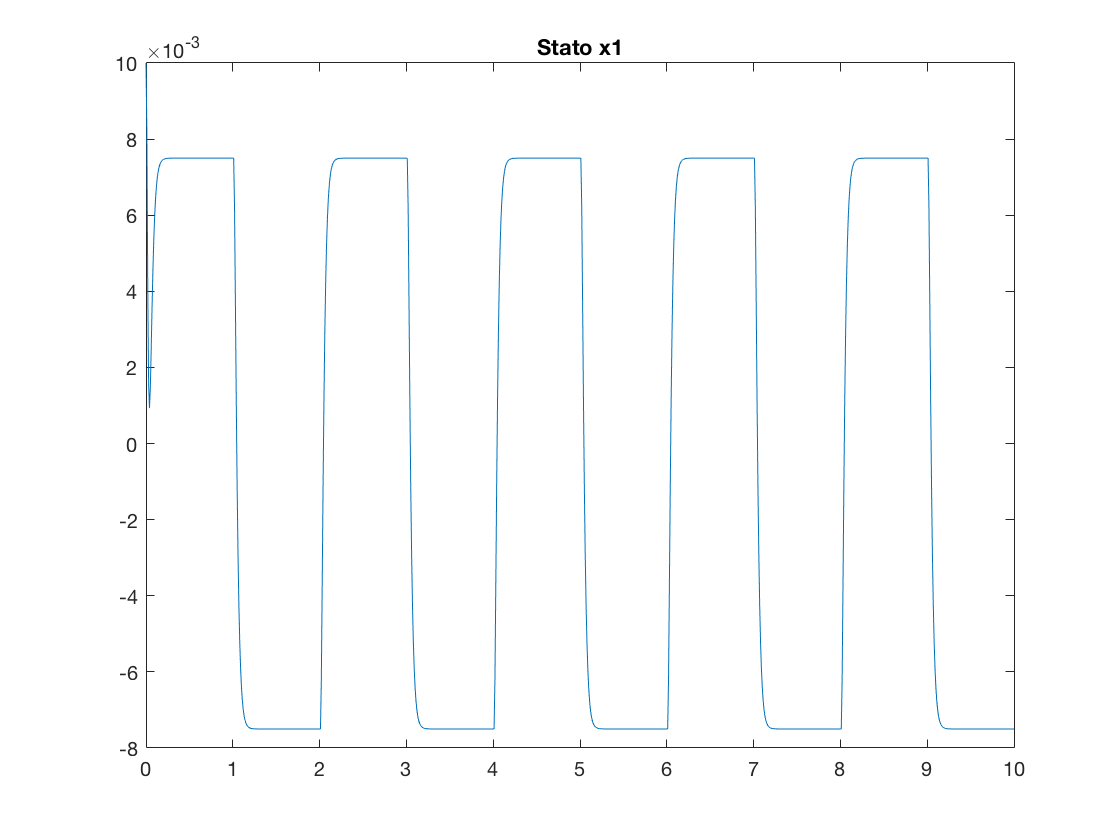


[Y, T, X] = lsim(sys_reg, r, t, x_0);
figure(1)
plot(T, X(:,1))
title('Stato x1')

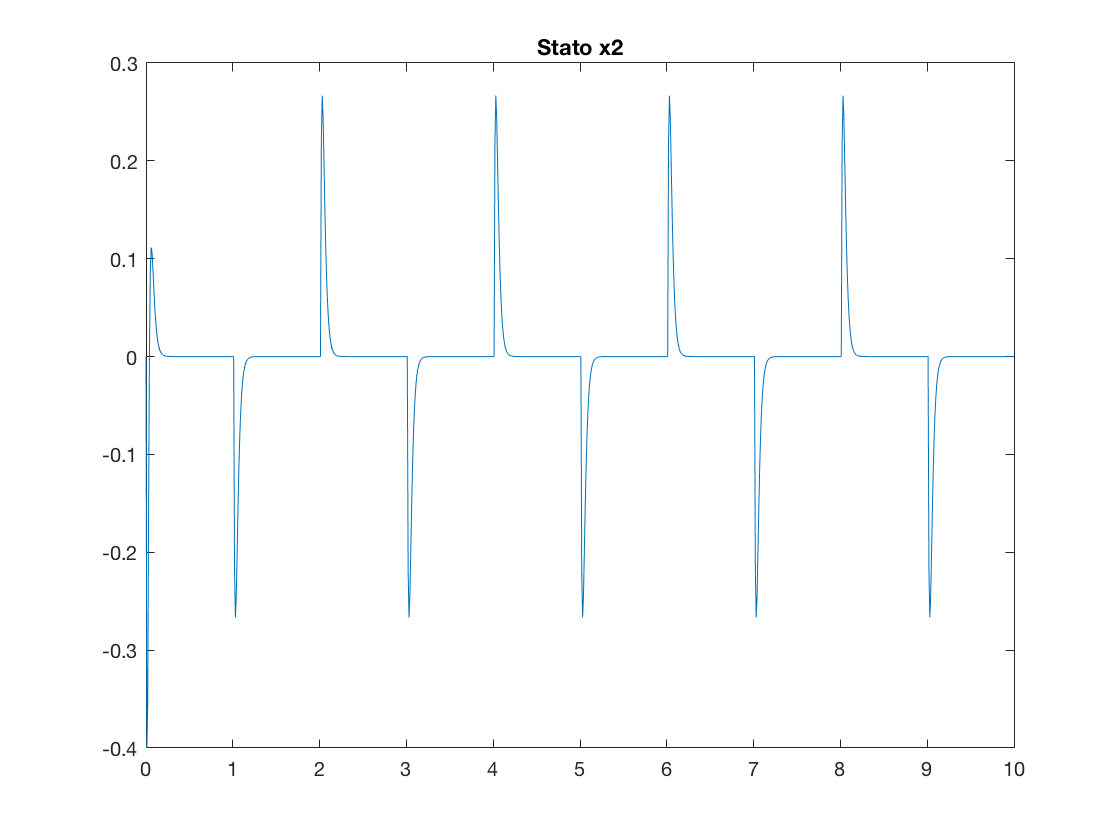


figure(2)
plot(T, X(:,2))
title('Stato x2')

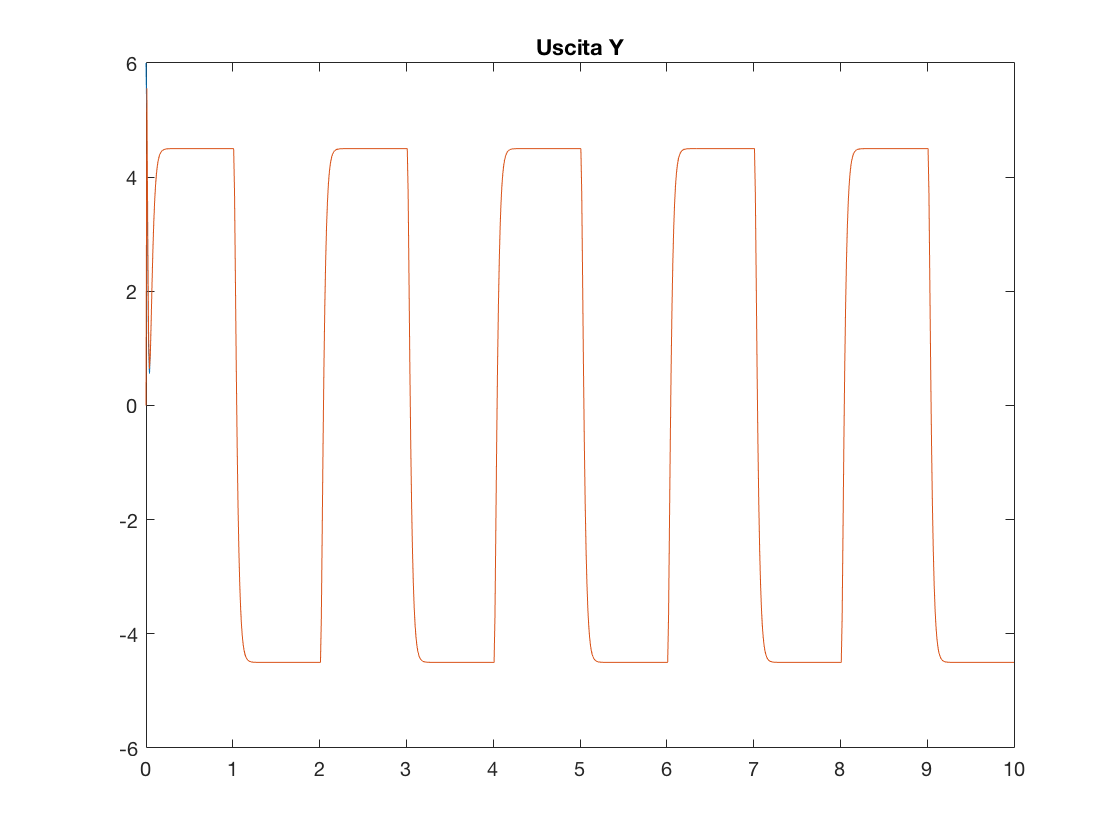


figure(3)
plot(T, Y)
title('Uscita Y')

x_0 3

x_0 = [-0.01; 0; 0; 0]

x_0 =    -0.0100
         0
         0
         0


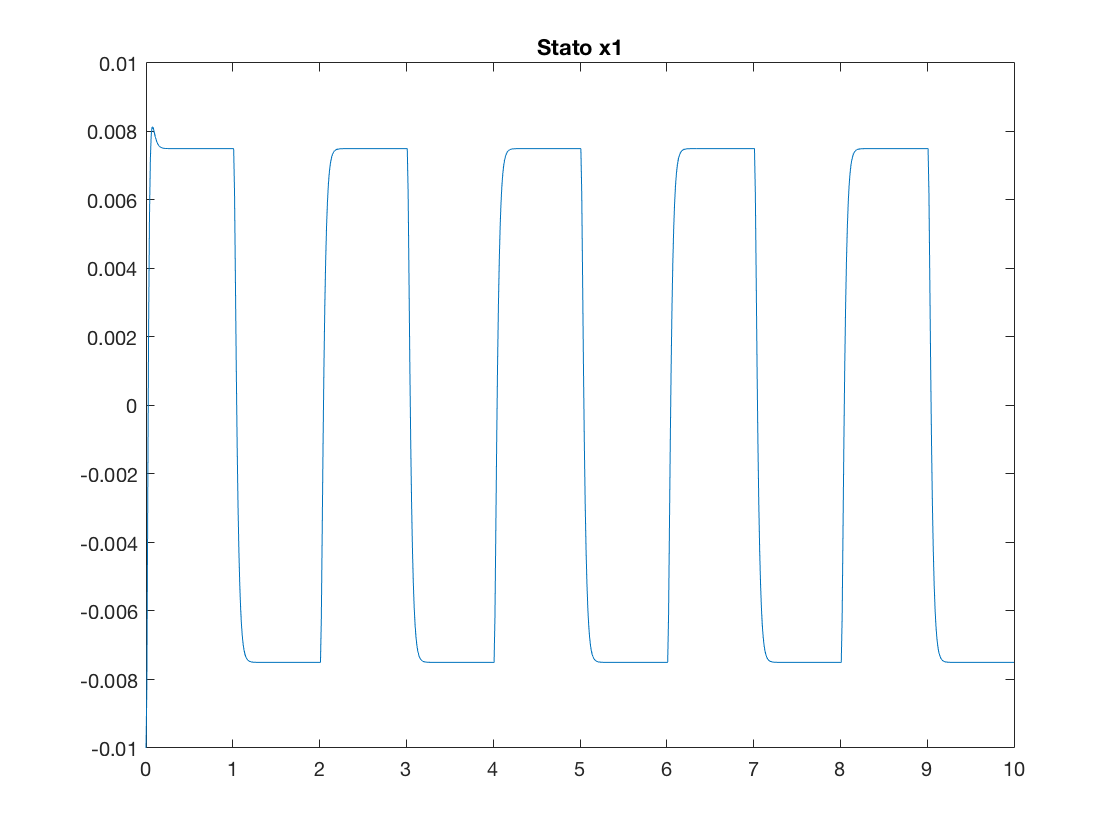


[Y, T, X] = lsim(sys_reg, r, t, x_0);
figure(1)
plot(T, X(:,1))
title('Stato x1')

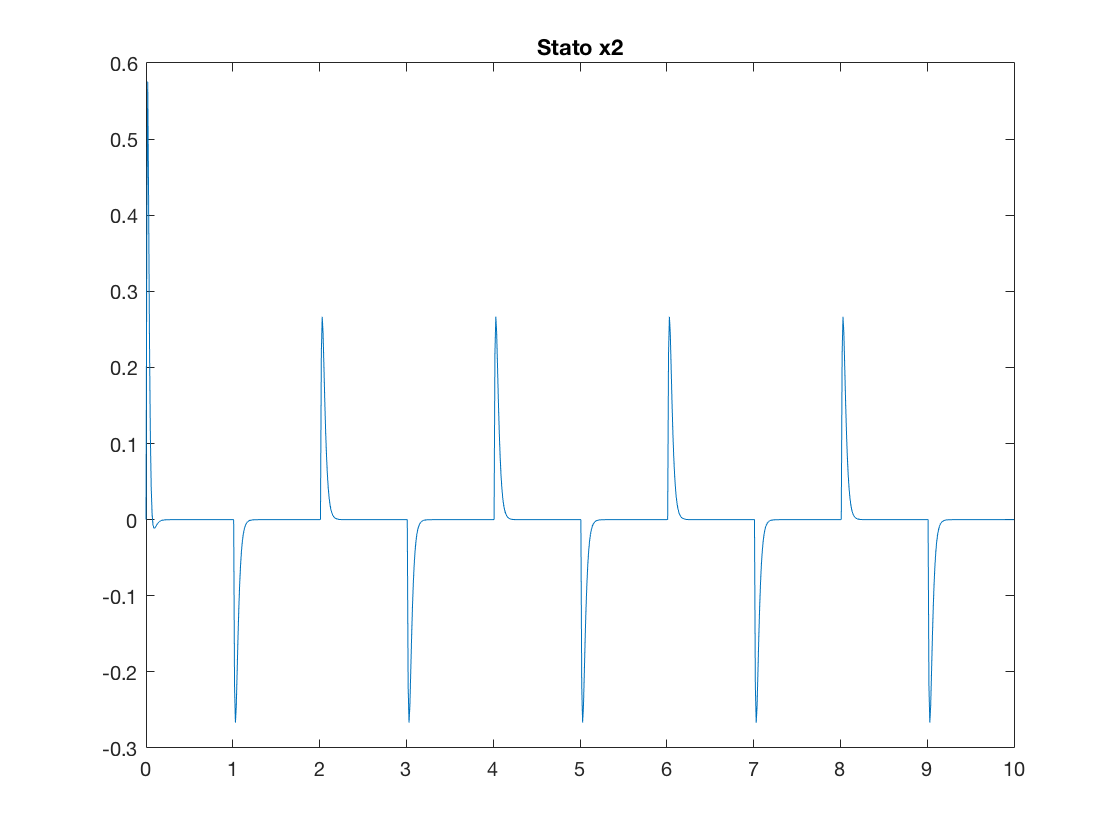


figure(2)
plot(T, X(:,2))
title('Stato x2')

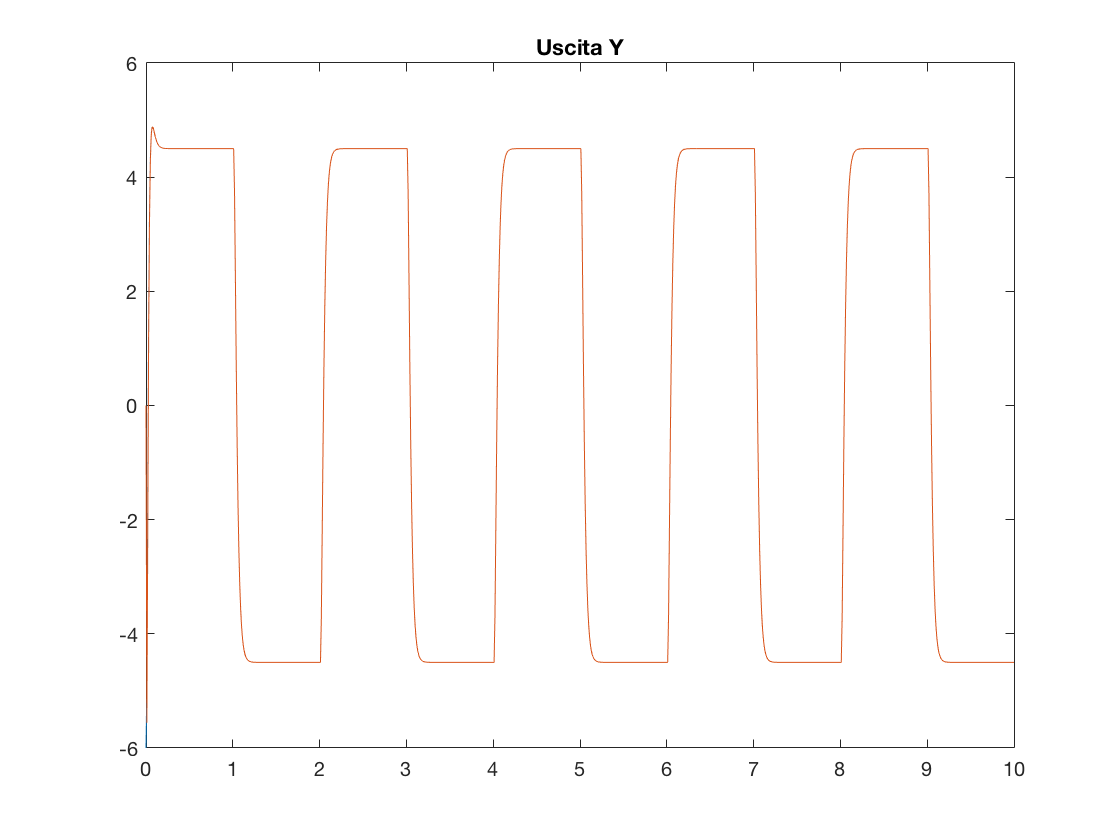


figure(3)
plot(T, Y)
title('Uscita Y')